# ASSIGNMENT 1

## Name: Muhammad Asad Imran Rafique

## Student ID: 48065145

## **1a)**

% Given Parameters
A = 0.8;
N = 2^10;
fs = 800e6;
Ts = 1/fs;
SNRdB = 0;
sigma = A * 10^(-SNRdB/10);
n = 1:N;
fx = 90e6 + rand*(110e6 - 90e6);
theta = -pi + 2*pi*rand;
% Creation of noisy signal
x = A * cos(2*pi*fx*n/fs + theta) + sigma * randn(1, N);
% Frequency Spectrum of noisy signal
X = fft(x);
% Finding index of maximum magnitude of the FFT result
[~, idx] = max(abs(X(2:N/2)));
% estimating the frequency of the maximum magnitude index
f_est = idx * fs / N;

disp(['True frequency: ' num2str(fx/1e6) ' MHz']);

True frequency: 98.534 MHz


disp(['Estimated frequency: ' num2str(f_est/1e6) ' MHz']);

Estimated frequency: 98.4375 MHz


## **1b)**

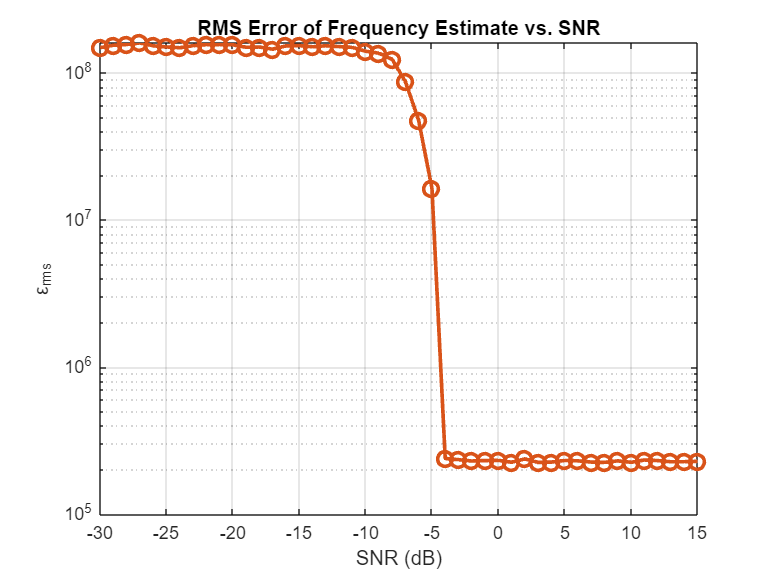

% Given Parameters
SNRdB_range = -30:15;
num_trials = 1000;

epsilon_rms = zeros(size(SNRdB_range));
% Outer loop for SNRdB Range
for i = 1:length(SNRdB_range)
    SNRdB = SNRdB_range(i);
    sigma = A * 10^(-SNRdB/10);
    epsilon = zeros(1, num_trials);
    % Inner loop for iterating 1000 times
    for trial = 1:num_trials
        n = 1:N;
        fx = 90e6 + rand*(110e6 - 90e6);
        theta = -pi + 2*pi*rand;
        x = A * cos(2*pi*fx*n/fs + theta) + sigma * randn(1, N);
        X = fft(x);
        [~, idx] = max(abs(X(2:N/2)));
        f_est = idx * fs / N;
        epsilon(trial) = abs(f_est - fx);
    end
    % Calculating rms error for each SNRdB in range
    epsilon_rms(i) = sqrt(mean(epsilon.^2));
end
% Plot of rms error against SNRdB 
figure;
semilogy(SNRdB_range, epsilon_rms, 'o-', 'LineWidth', 2, 'MarkerSize', 8, 'Color', [0.8500 0.3250 0.0980]);
xlabel('SNR (dB)');
ylabel('ε_{rms}');
title('RMS Error of Frequency Estimate vs. SNR');
grid on;

## **1c) **

Low SNR (High Noise):

- In situations where the SNR is low (high noise), the noise component significantly affects the received signal. As a result:

- The noise introduces fluctuations and distortion, making it challenging to distinguish the true signal from the noise.

- The frequency estimation algorithm may mistakenly identify noise fluctuations as signal characteristics, leading to inaccuracies in the estimate.

- This uncertainty caused by the noise imposes an upper bound on the accuracy of the frequency estimate. No matter how sophisticated the estimation algorithm, the presence of substantial noise limits the achievable accuracy.

High SNR (Low Noise):

- Conversely, in scenarios with high SNR (low noise), the signal dominates over the noise component in the received signal. Consequently:

- The received signal closely resembles the true underlying signal, with minimal distortion caused by noise.

- The frequency estimation algorithm can accurately identify the signal characteristics, leading to precise frequency estimates.

- Despite the low noise level, there still exists a lower bound on the rms error. This lower bound is determined by factors such as:

- Resolution limitations of the sampling frequency: Even with low noise, the discrete nature of the sampled signal may introduce quantization errors, limiting the precision of the frequency estimate.

- Imperfections or limitations in the estimation algorithm: No estimation algorithm is entirely free from bias or errors, which can contribute to a non-zero rms error even under ideal conditions.

## **2a)**

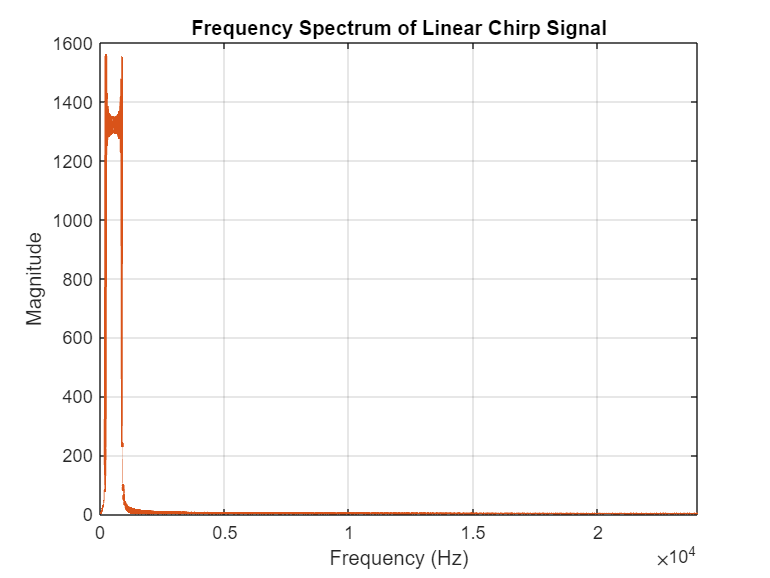

% Given Parameters
f0 = 220;
mu = 330;
fs = 48000;
duration = 2;
% Defining the Time Vector
t = 0:1/fs:duration;
% Generating Chirp Signal
f_t = f0 + mu * t;
x = cos(2*pi * cumsum(f_t) / fs);
% Playing the chirp sound
sound(x, fs);
% Computing and Plotting the Frequency Spectrum
nfft = 2^nextpow2(length(x));
X = fft(x, nfft);
frequencies = fs/2 * linspace(0,1,nfft/2+1);
figure;
plot(frequencies, abs(X(1:nfft/2+1)), 'LineWidth', 1.5, 'Color', [0.8500 0.3250 0.0980]);
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Frequency Spectrum of Linear Chirp Signal');
grid on;
xlim([0, max(frequencies)]);

## **2b)**

% Defining Tau Values
tau_values = [0.2, 2, 10, 40, 100, 200] * 1e-3;
% Looping over Tau Values
for i = 1:length(tau_values)
    tau = tau_values(i);
    delay = tau * fs; % Delay shift
    X = fft(x); % FFT of chirp signal
    delay_filter = exp(-1j * 2 * pi * delay * (0:length(X)-1) / length(X)); %Constructing Phase Shift Filter
    X_delayed = X .* delay_filter; % Applying Phase Shift Filter to chirp signal
    x_delayed = ifft(X_delayed); % IFFT of filtered signal
    y = x + x_delayed; % Accumulation
    y = y / max(abs(y)); % Normalisation
    sound(real(y), fs); % Playing Phase Shifted Audio
    pause(duration + 0.5);
end

## **2c)**

% Defining Parameters
block_size = 4096;
% Looping over Tau Values
for i = 1:length(tau_values)
    tau = tau_values(i);
    delay = tau * fs; % Number of samples to shift  
    y = zeros(size(x));
    % Block Processing for FFT and IFFT stage
    % Overlapp Add Method
    for j = 1:ceil(length(x)/block_size)
        idx_start = (j-1) * block_size + 1;
        idx_end = min(j * block_size, length(x));
        x_block = x(idx_start:idx_end);
        X_block = fft(x_block, block_size);  % FFT of chirp signal block
        delay_filter = exp(-1j * 2 * pi * delay * (0:block_size-1) / fs); %Constructing Phase Shift Filter
        X_block_delayed = X_block .* delay_filter; % Applying Phase Shift Filter to chirp signal block
        x_block_delayed = ifft(X_block_delayed, block_size); % IFFT of filtered signal block
        y(idx_start:idx_end) = x_block + x_block_delayed(1:length(x_block)); % Overlap - Add
    end    
    y = y / max(abs(y)); % Normalisation
    sound(real(y), fs); % Playing Phase Shifted Audio
    pause(duration + 0.5);
end

## **3a)**

load('audiodata.mat');
M = 12;
x_downsampled = downsample(x, M);
start_idx = 8 * fs / M;
end_idx = 15 * fs / M;

sound(x(start_idx*M:end_idx*M), fs);

sound(x_downsampled(start_idx:end_idx), fs/M);

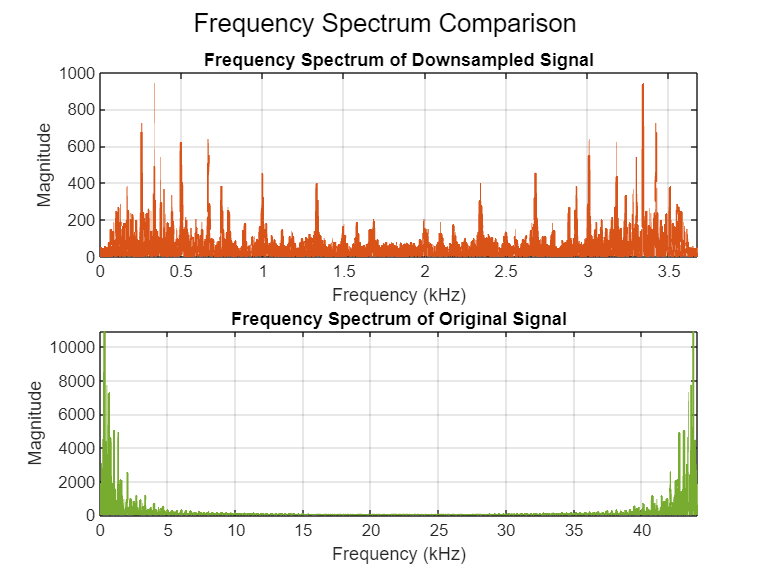

N = length(x); 
N_downsampled = length(x_downsampled); 

X = fft(x);
X_downsampled = fft(x_downsampled);

f_original = (0:N-1) * fs / N;
f_downsampled = (0:N_downsampled-1) * (fs/M) / N_downsampled;

figure;

% Plot for Downsampled Signal
subplot(2,1,1);
plot(f_downsampled/1000, abs(X_downsampled(1:N_downsampled)), 'LineWidth', 1.5, 'Color', [0.8500 0.3250 0.0980]);
xlabel('Frequency (kHz)');
ylabel('Magnitude');
title('Frequency Spectrum of Downsampled Signal');
grid on;
xlim([min(f_downsampled)/1000, max(f_downsampled)/1000]);

% Plot for Original Signal
subplot(2,1,2);
plot(f_original/1000, abs(X(1:N)), 'LineWidth', 1.5, 'Color', [0.4660 0.6740 0.1880]);
xlabel('Frequency (kHz)');
ylabel('Magnitude');
title('Frequency Spectrum of Original Signal');
grid on;
xlim([min(f_original)/1000, max(f_original)/1000]);

sgtitle('Frequency Spectrum Comparison');

## **3b)**

load("lowpass_3b.mat");
x_filtered = conv(x, lowpass_3b, 'same');
x_decimated = downsample(x_filtered, M);

sound(x_decimated(start_idx:end_idx), fs/M);

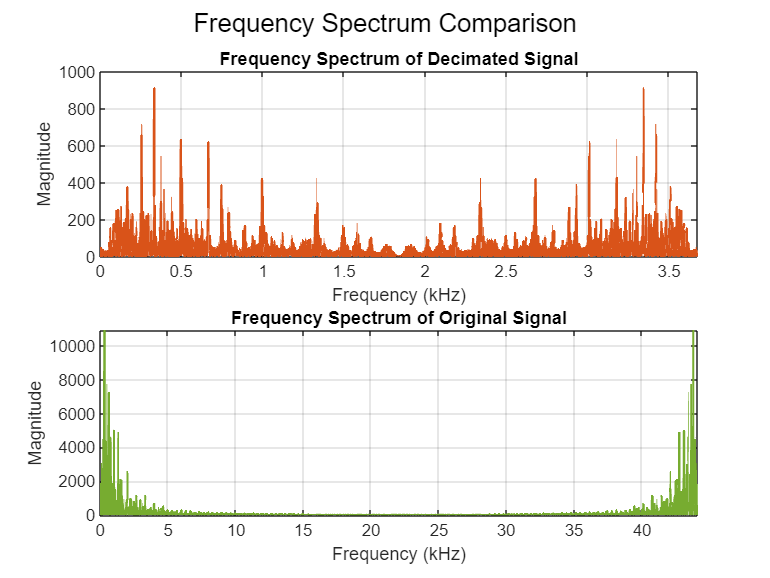

N_decimated = length(x_decimated); 
X_decimated = fft(x_decimated);
f_decimated = (0:N_decimated-1) * (fs/M) / N_decimated;
figure;

subplot(2,1,1);
plot(f_decimated/1000, abs(X_decimated(1:N_decimated)), 'LineWidth', 1.5, 'Color', [0.8500 0.3250 0.0980]);
xlabel('Frequency (kHz)');
ylabel('Magnitude');
title('Frequency Spectrum of Decimated Signal');
grid on;
xlim([min(f_decimated)/1000, max(f_decimated)/1000]);

subplot(2,1,2);
plot(f_original/1000, abs(X(1:N)), 'LineWidth', 1.5, 'Color', [0.4660 0.6740 0.1880]);
xlabel('Frequency (kHz)');
ylabel('Magnitude');
title('Frequency Spectrum of Original Signal');
grid on;
xlim([min(f_original)/1000, max(f_original)/1000]);

sgtitle('Frequency Spectrum Comparison');

## **3c)**

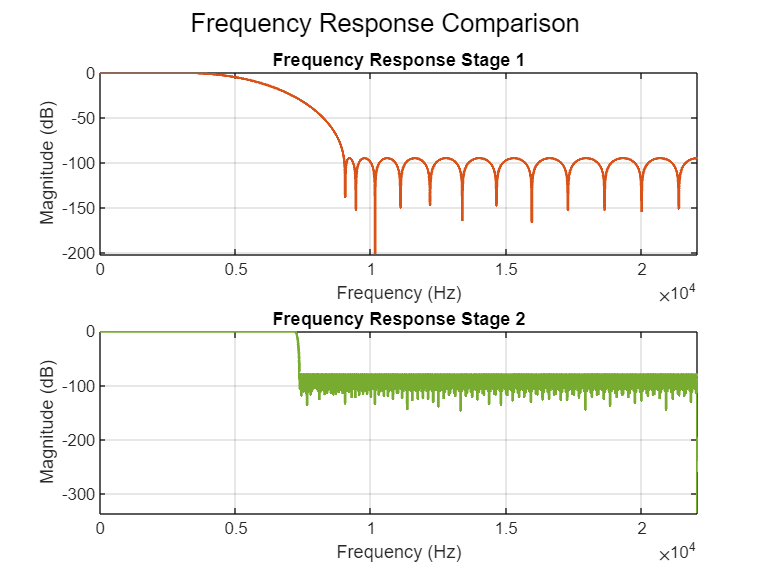

load("lowpass_multistage_1.mat");
load("lowpass_multistage_2.mat");

f_range = linspace(0, fs/2,10000);

[H1, ~] = freqz(lowpass_multistage_1, 1, f_range, fs);
[H2, ~] = freqz(lowpass_multistage_2, 1, f_range, fs);

figure;

% Plot for Stage 1
subplot(2,1,1);
plot(f_range, 20*log10(abs(H1)), 'LineWidth', 1.5, 'Color', [0.8500 0.3250 0.0980]);
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Frequency Response Stage 1');
grid on;
xlim([min(f_range), max(f_range)]);
ylim([min(20*log10(abs(H1))), max(20*log10(abs(H1)))]);

% Plot for Stage 2
subplot(2,1,2);
plot(f_range, 20*log10(abs(H2)), 'LineWidth', 1.5, 'Color', [0.4660 0.6740 0.1880]);
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Frequency Response Stage 2');
grid on;
xlim([min(f_range), max(f_range)]);
ylim([min(20*log10(abs(H2))), max(20*log10(abs(H2)))]); 

sgtitle('Frequency Response Comparison');

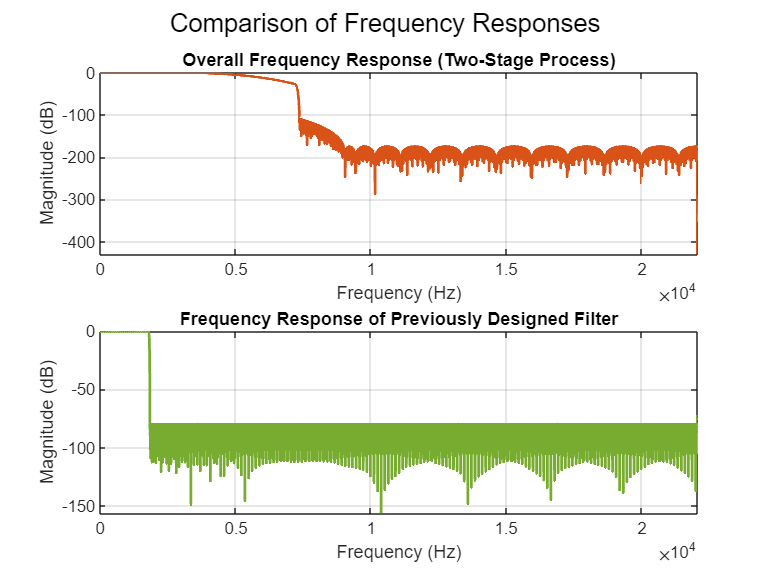


H_overall_two_stage = H1 .* H2;
[H_previously_designed, ~] = freqz(lowpass_3b, 1, f_range, fs);
figure;

% Plot for Overall Two-Stage Process
subplot(2,1,1);
plot(f_range, 20*log10(abs(H_overall_two_stage)), 'LineWidth', 1.5, 'Color', [0.8500 0.3250 0.0980]);
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Overall Frequency Response (Two-Stage Process)');
grid on;
xlim([min(f_range), max(f_range)]);
ylim([min(20*log10(abs(H_overall_two_stage))), max(20*log10(abs(H_overall_two_stage)))]);

% Plot for Previously Designed Filter
subplot(2,1,2);
plot(f_range, 20*log10(abs(H_previously_designed)), 'LineWidth', 1.5, 'Color', [0.4660 0.6740 0.1880]);
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Frequency Response of Previously Designed Filter');
grid on;
xlim([min(f_range), max(f_range)]);
ylim([min(20*log10(abs(H_previously_designed))), max(20*log10(abs(H_previously_designed)))]);

sgtitle('Comparison of Frequency Responses');

x_filter_stage1 = filter(lowpass_multistage_1,1,x);
x_deci_stage1 = downsample(x_filter_stage1, 4);
x_filter_stage2 = filter(lowpass_multistage_2,1,x_deci_stage1);
x_deci_stage2 = downsample(x_filter_stage2, 3);

sound(x_deci_stage1(start_idx*3:end_idx*3), fs/4);

sound(x_deci_stage2(start_idx:end_idx), fs/M);

## **3d)**

Given Fs = 44100 Hz and F_stop,1 = 9000 Hz, we can calculate F_Nyquist for the first stage of decimation.

- Calculate the sampling rate after the first stage of decimation:

Fs_1 = Fs/M1 = 11025 Hz

- Calculate the Nyquist frequency for the first stage:

F_Nyquist = (Fs_1)/2 = 5512.5 Hz

Now, let's address whether aliasing interference from the first stage is propagated to and retained after the second stage:

Since F_Nyquist = 5512.5 Hz < F_stop,1 = 9000 Hz, it indicates that some aliasing interference may occur during the first stage of decimation.

However, during the second stage the sampling rate is further reduced and the second lowpass filter is designed to remove any remaining frequency components above the Nyquist frequency of the second stage. Therefore, while some aliasing interference may occur during the first stage, it is addressed and mitigated during the subsequent stages, ensuring that the final output does not retain significant aliasing interference. The frequency response of both stages illustrates this properly.

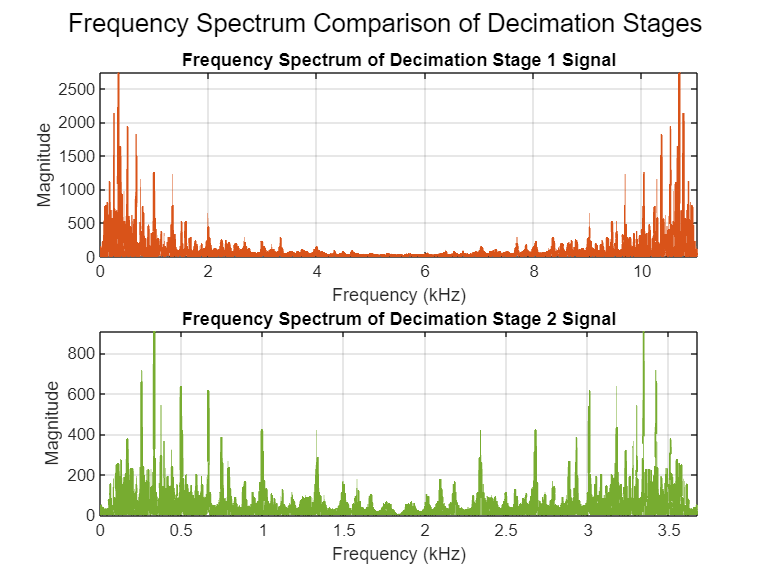

N_stage1 = length(x_deci_stage1);
frequencies_stage1 = (0:N_stage1-1) * (fs/4) / N_stage1;
X_stage1 = abs(fft(x_deci_stage1));

N_stage2 = length(x_deci_stage2);
frequencies_stage2 = (0:N_stage2-1) * (fs/M) / N_stage2;
X_stage2 = abs(fft(x_deci_stage2));

figure;

% Plot for Decimation Stage 1 Signal
subplot(2,1,1);
plot(frequencies_stage1/1000, X_stage1, 'LineWidth', 1.5, 'Color', [0.8500 0.3250 0.0980]);
xlabel('Frequency (kHz)');
ylabel('Magnitude');
title('Frequency Spectrum of Decimation Stage 1 Signal');
grid on;
xlim([min(frequencies_stage1/1000), max(frequencies_stage1/1000)]);
ylim([0, max(X_stage1)]);

% Plot for Decimation Stage 2 Signal
subplot(2,1,2);
plot(frequencies_stage2/1000, X_stage2, 'LineWidth', 1.5, 'Color', [0.4660 0.6740 0.1880]);
xlabel('Frequency (kHz)');
ylabel('Magnitude');
title('Frequency Spectrum of Decimation Stage 2 Signal');
grid on;
xlim([min(frequencies_stage2/1000), max(frequencies_stage2/1000)]);
ylim([0, max(X_stage2)]);

sgtitle('Frequency Spectrum Comparison of Decimation Stages');